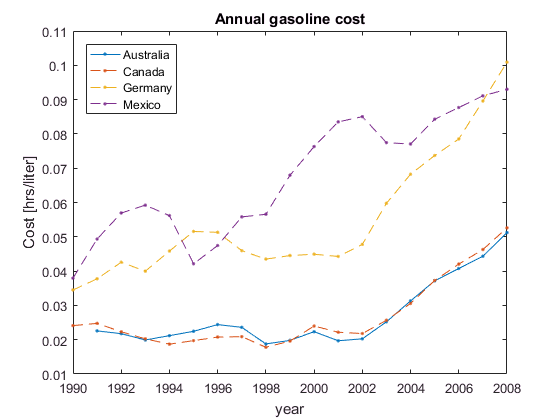

load gCosts.mat

Australia = gal2lit*Australia/hourlyAus;
Canada = gal2lit*Canada/hourlyCan;
Germany = gal2lit*Germany/hourlyGer;
Mexico = gal2lit*Mexico/hourlyMex;

plot(Year,Australia,'.-')
hold on
plot(Year,Canada,'.--')
plot(Year,Germany,'.--')
plot(Year,Mexico,'.--')
hold off

title('Annual gasoline cost')
xlabel('year')
ylabel('Cost [hrs/liter]')

legend(country,'Location','northwest')

## Fluctuation between australia and canada

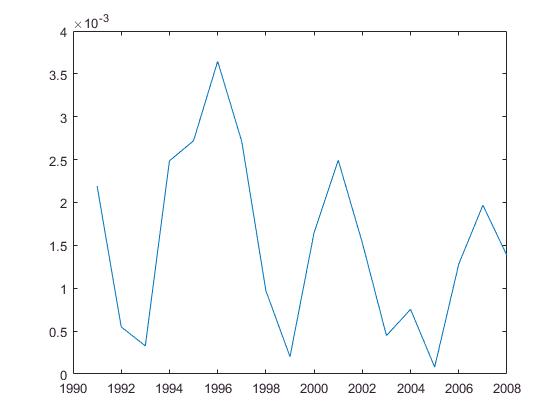

AuCaDiff = abs(Canada - Australia);

plot(Year, AuCaDiff)


doc elfun


h = [1 2 3 4]

h =      1     2     3     4

sin(h)

ans =     0.8415    0.9093    0.1411   -0.7568

## statistical functions

% mean absolute value of fluctuation
avgDiff = mean(AuCaDiff, 'omitnan')

avgDiff = 0.0015

nanmean(AuCaDiff)

ans = 0.0015


doc datafun


Australia(1) = Australia(2)

Australia =     0.0226
    0.0226
    0.0218
    0.0199
    0.0212
    0.0224
    0.0244
    0.0236
    0.0188
    0.0198

Australia(1) = Australia(end-1)

Australia =     0.0443
    0.0226
    0.0218
    0.0199
    0.0212
    0.0224
    0.0244
    0.0236
    0.0188
    0.0198


Aus90 = Australia(1)

Aus90 = 0.0443

## Years from 1990-2008

x = 1990:2008

x =         1990        1991        1992        1993        1994        1995        1996        1997        1998        1999        2000        2001        2002        2003        2004        2005        2006        2007        2008

eox = 1990:2:2008

eox =         1990        1992        1994        1996        1998        2000        2002        2004        2006        2008

partx = linspace(1990,2008,4)

partx =         1990        1996        2002        2008

L = length(partx)

L = 4


% find when the biggest difference between canada and australia
% occured

[x,idx] = max(AuCaDiff)

x = 0.0036

idx = 7

Year(idx)

ans = 1996


% 1st, 4th, 7-9th year
Year(1)

ans = 1990

Year(4)

ans = 1993


Year([1 4 7:9])

ans =         1990
        1993
        1996
        1997
        1998

Year(7:9)

ans =         1996
        1997
        1998


Mex90s = Mexico(1:10);
Mex00s = Mexico(11:end);

d90s = mean(Mex90s)

d90s = 0.0530

d00s = mean(Mex00s)

d00s = 0.0839

h = [1 2 3 7 16];
diff(h)

ans =      1     1     4     9


d90s = mean(diff(Mex90s))

d90s = 0.0033

d00s = mean(diff(Mex00s))

d00s = 0.0021

[MexicoSorted,Midx] = sort(Mexico);
SortedYears = Year(Midx)

SortedYears =         1990
        1995
        1996
        1991
        1997
        1994
        1998
        1992
        1993
        1999

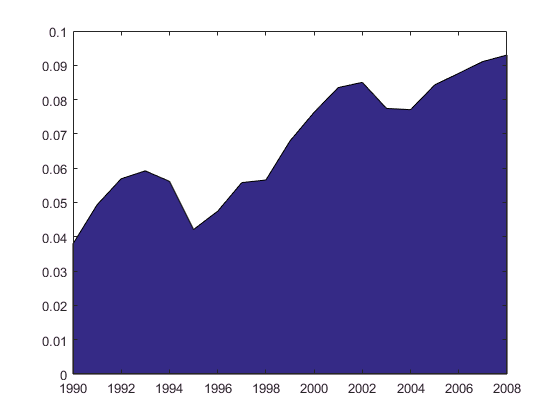


area(Year,Mexico)

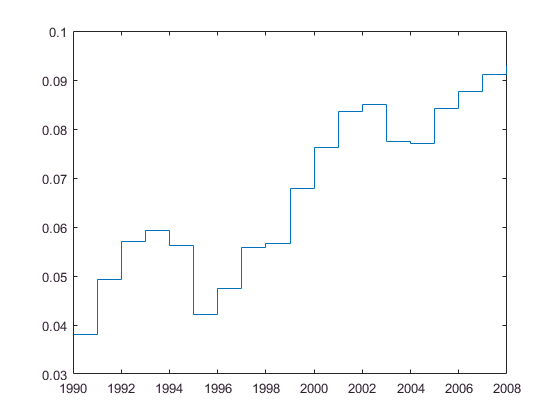

stairs(Year,Mexico)

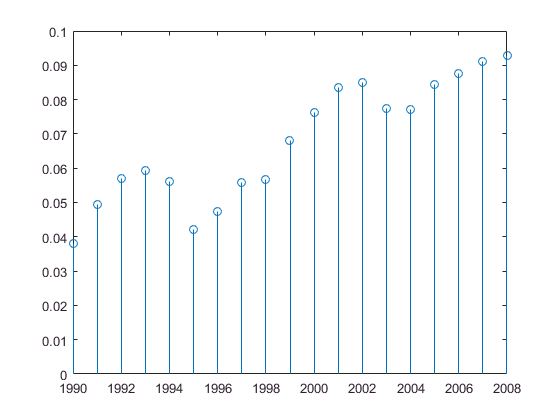

stem(Year,Mexico)

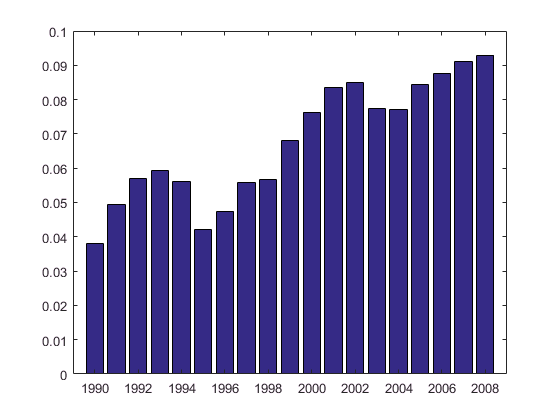

bar(Year,Mexico)

xlim([1989 2009])

scatter(Australia,Canada)
AuLimits = xlim

AuLimits =     0.0150    0.0550

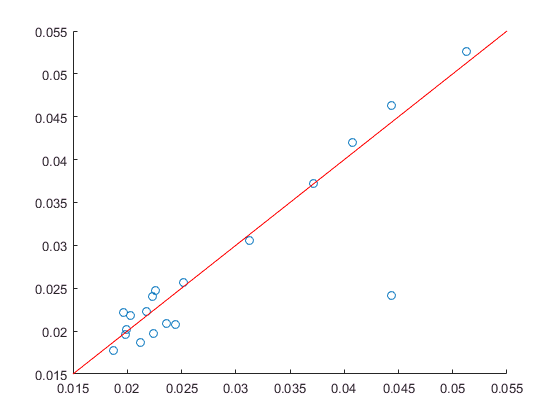

hold on
plot(AuLimits,AuLimits,'r')
hold off

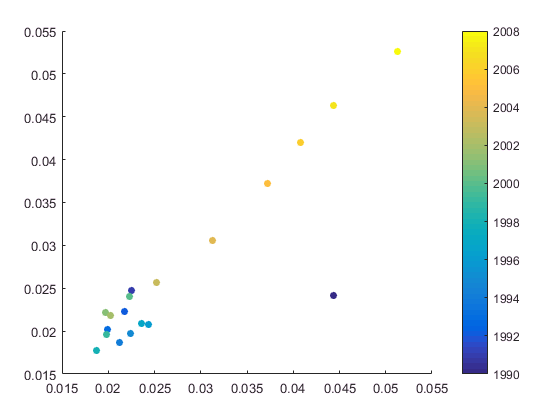

scatter(Australia,Canada,30,Year,'Filled')
colorbar